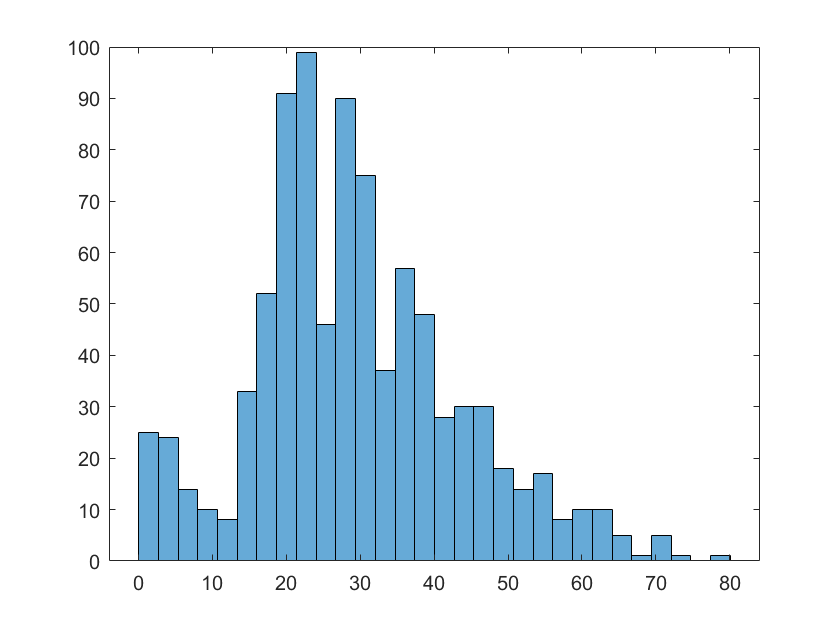

%assumes you have used ImportData and included the titanic_data.csv file
filename = 'titanic_data.csv';
dataset = xlsread(filename);
%xlsread titanic_data.csv;
age = dataset(:,4);

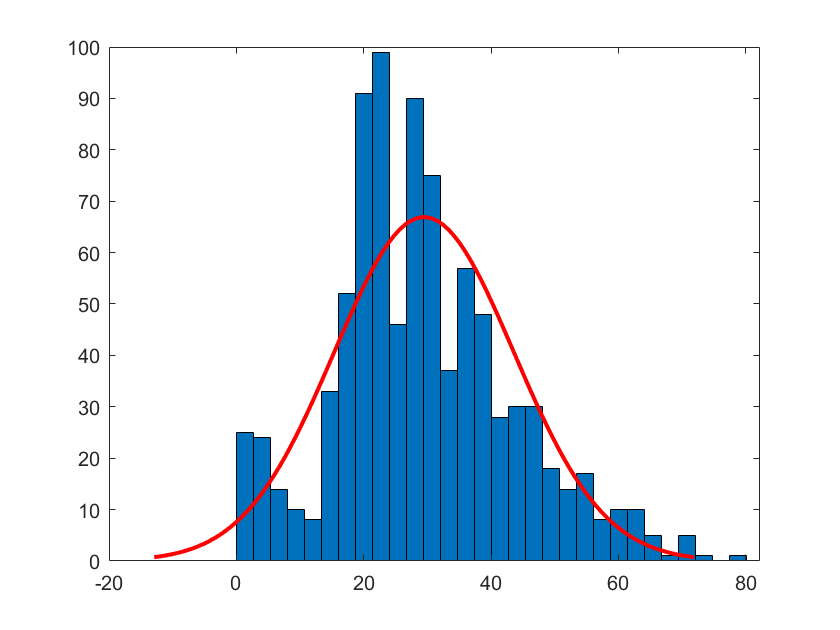

histfit(age)

%Violin Plot of violin plot detailing the age 
% distribution, separated by survivors and deceased
indices1 = dataset(:,1) == 1; %Get the incides of all survivors
survivors = dataset(indices1,:); %Save dataset of survivors

indices2 = dataset(:,1) == 0; %Get indices of everyone who died
deceased = dataset(indices2,:);


Undefined function or variable 'violinplot'.

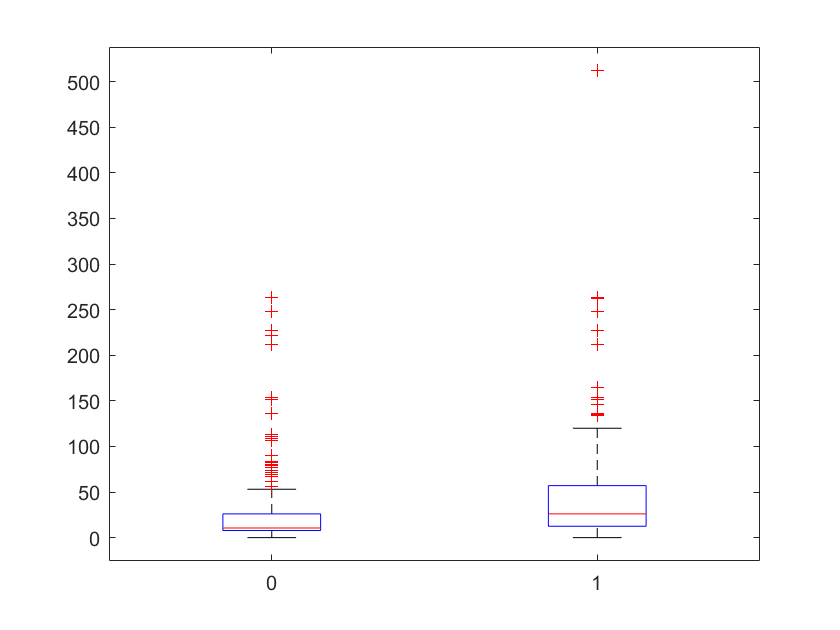

%Observation 3:
%Box plot summarizing the fare distribution, 
%separated by survivors and deceased
boxplot(dataset(:,7),dataset(:,1))

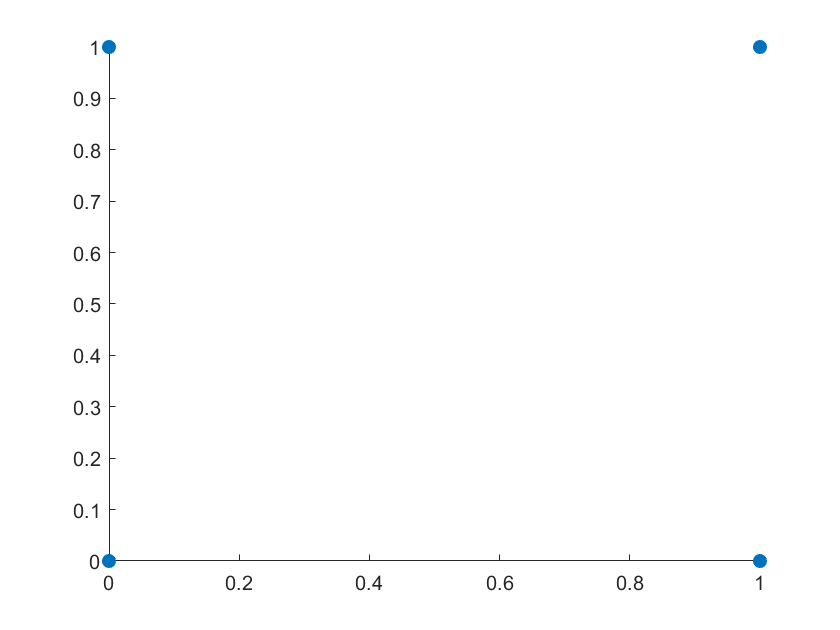

%Observation 4:
%a scatter plot of gender vs. survival
scatter(dataset(:,3),dataset(:,1),50,'filled')

%Observation 5: histogram showing the distribution of 
% survivors as a function of gender
ONLYSURVIVORS = survivors(:,3);
histfit(ONLYSURVIVORS)

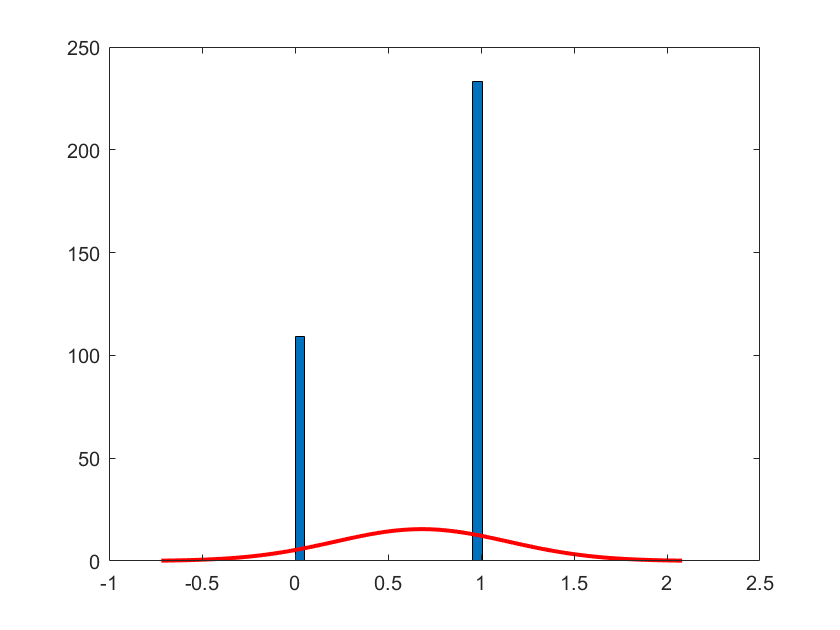

%Observation 6:
GenderNSurvival = dataset(:,[3]);

histfit(GenderNSurvival)
